[x, fs] = audioread('instru1.wav');
X = abs(fft(x));
[max_magnitude, idx] = max(X);
fundamental_frequency = (idx - 1) * fs / numel(x)

fundamental_frequency = 524.3338

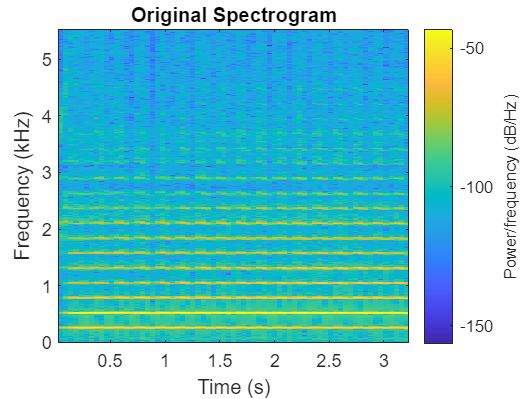



window_length = 1024;
overlap = window_length / 2;

figure;
spectrogram(x, window_length, overlap, [], fs, 'yaxis');
title('Original Spectrogram');

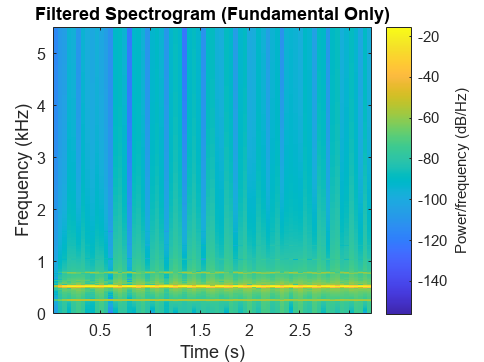



fundamental_frequency =  524.3338; 


lower_cutoff = 2 * pi * (fundamental_frequency - 10) / fs;
upper_cutoff = 2 * pi * (fundamental_frequency + 10) / fs;


N = 101; 
h = fir1(N - 1, [lower_cutoff / pi, upper_cutoff / pi], 'bandpass', hann(N));


filtered_signal = filter(h, 1, x);


filtered_signal = filtered_signal / max(abs(filtered_signal));


audiowrite('filtered_output_bandpass.wav', filtered_signal, fs)

figure;
spectrogram(filtered_signal, window_length, overlap, [], fs, 'yaxis');
title('Filtered Spectrogram (Fundamental Only)');



sound(filtered_signal, fs);
X = abs(fft(filtered_signal));
[max_magnitude, idx] = max(X);
fundamental_frequency = (idx - 1) * fs / numel(filtered_signal)

fundamental_frequency = 524.3338